# Paper2 Fig3

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large'};


Choose from the list, but input can take everything between 0-180

AngleInpt = 60; % has to be multiples of 7.5
RotInd = floor(AngleInpt/45); % 0-3
MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
switch MirInd % find the corresponding source
    case 0
        AngSource = mod(AngleInpt,45);
    case 1
        AngSource = mod(-AngleInpt,45);    
end

% Use the source, decide which response function for angle should I use
AngFuncCtgrCdid = 0:7.5:22.5; 
[~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

AngPrint = AngleList{AngFuncCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

Large = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{2}),...
    'LDEFrfunc','L4EmeshX','L4ImeshY');
L4EmeshXLarge = Large.L4EmeshX;
L4ImeshYLarge = Large.L4ImeshY;
LDEFrfuncLarge = Large.LDEFrfunc;

Small = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{1}),...
    'LDEFrfunc','L4EmeshX','L4ImeshY');
L4EmeshXSmall = Small.L4EmeshX;
L4ImeshYSmall = Small.L4ImeshY;
LDEFrfuncSmall = Small.LDEFrfunc;

## 3. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;

ICTestAll = cell(1,1);

Background

% load('LDETraces_ang15.0.mat')
% LDEbgIC = LDEEpoOut{end};
% LDEbgIC.S(:) = 2.5;
% LDEbgIC.C(:) = 8;
% LDEbgIC.I(:) = 16;
% ICTestAll{1} = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

load('LDETraces_ang0.0.mat')
LDEICPart = LDEEpoOut{end};


LDEICPart = HCRot(LDEICPart,0,N_HCOut,NPixX,NPixY,0);
ICTestAll{1} = LDEICPart;
LDEOutAll = cell(size(ICTestAll));

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
LGNlist = 4; L6list = 4;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.10;
Trunc = 1.0;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,Trunc,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

MirInd = logical(MirInd);
for Ctgr = 1:4
    PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
    PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
end

PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

start iteration

p = 0.2; % 1-p for the original input
EpocTest = 300;
tic
for TestInd = 1:length(ICTestAll)
    ICUse = ICTestAll{TestInd};
    IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);
    
    % for <10 iterations, use large domain, otherwise use small
    
    [LargeIter,~,~,~,~] = ...
        LDEIteration_16FuncMain(...
        PixInptCtgrUse,IniTest,p,20,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXLarge,L4ImeshYLarge,LDEFrfuncLarge,...
        N_HCOut,NPixX,NPixY)  ;
    
    [SmallIter,~,~,~,~] = ...
        LDEIteration_16FuncMain(...
        PixInptCtgrUse,LargeIter{end},p,EpocTest,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXSmall,L4ImeshYSmall,LDEFrfuncSmall,...
        N_HCOut,NPixX,NPixY)  ;
    LDEOutAll{TestInd} = [LargeIter;SmallIter]; 
    LDEEquv = LDEOutAll{TestInd}{end};
    
    for EpcInd = 1:EpocTest+1
        LDEPertRslt = LDEOutAll{TestInd}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        
        L2Diff_OneStepAll(TestInd,EpcInd) = ...
            sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestInd,EpcInd,:) = [SDiff;CDiff;IDiff];
    end
end
toc

Elapsed time is 12.248758 seconds.


## 4. Make Fig3

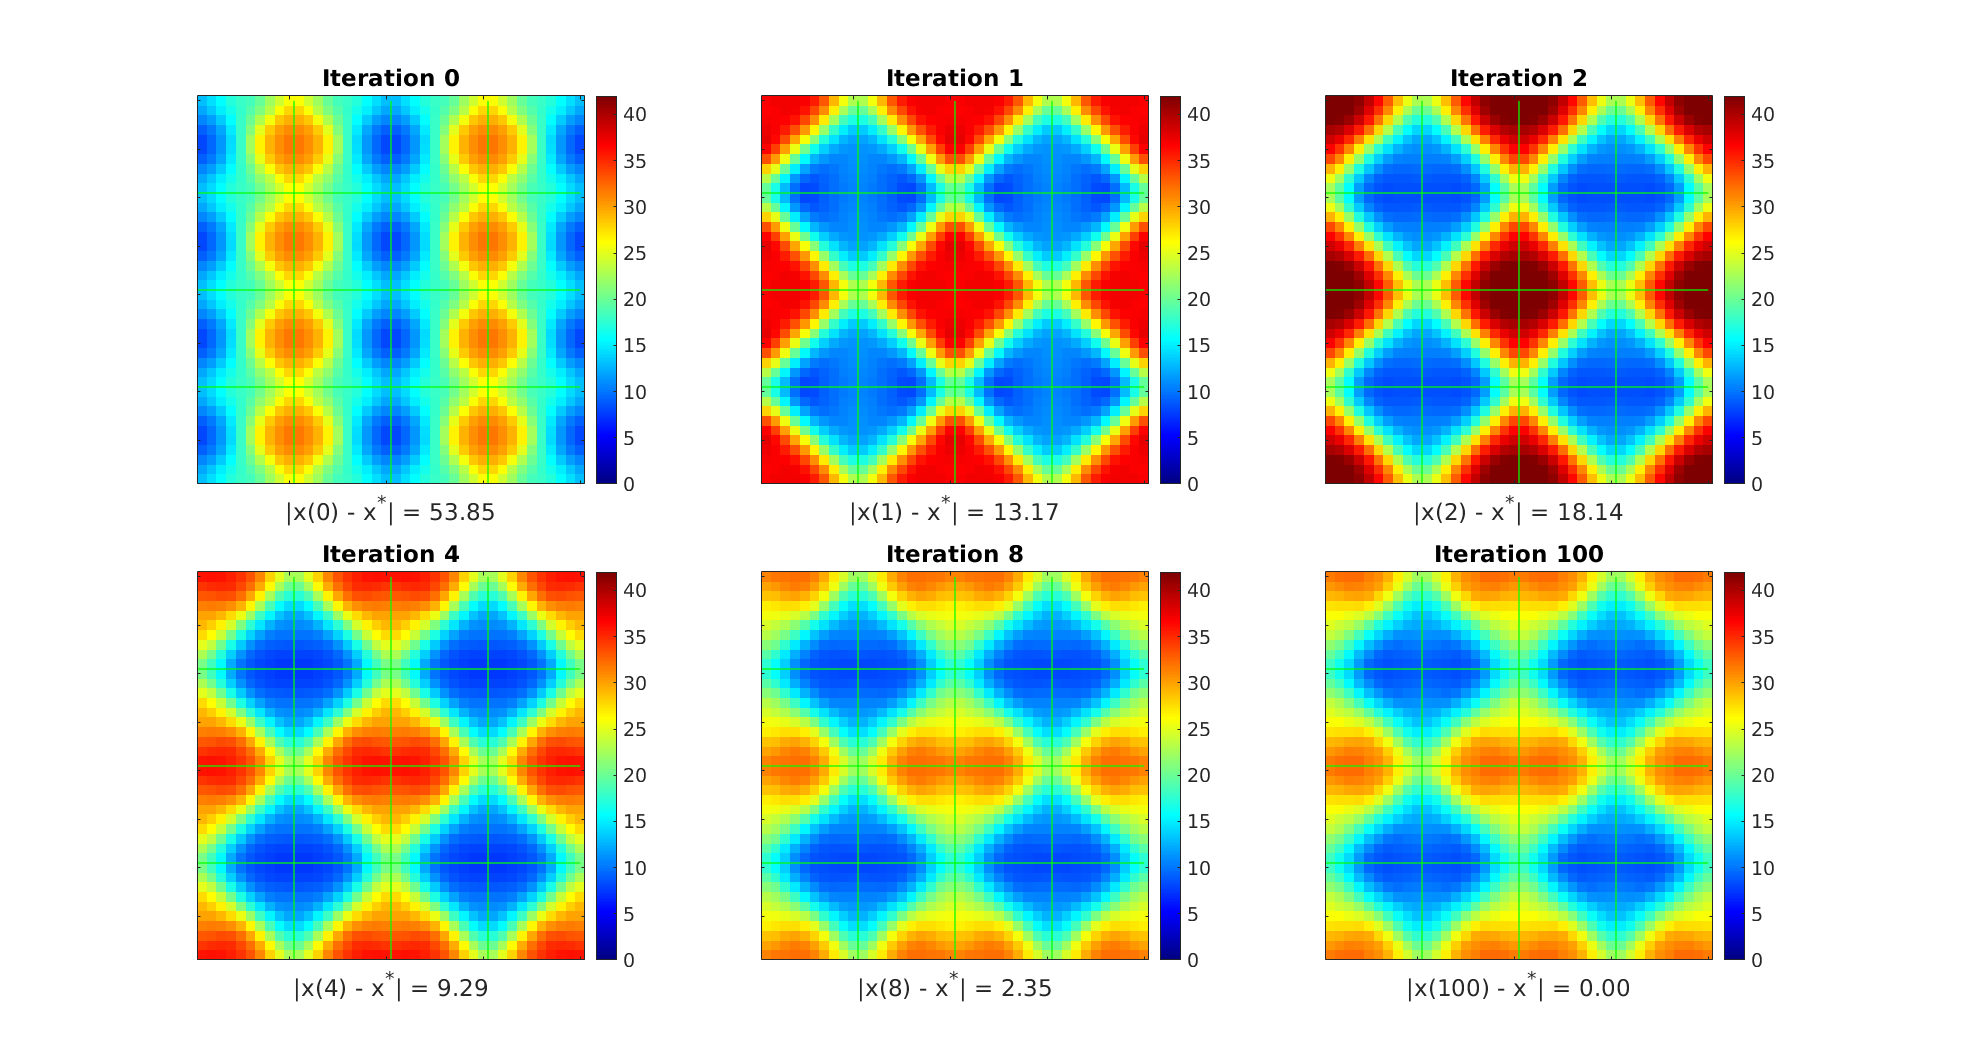

Fig3 = figure("Name",sprintf('%.1f',AngleInpt),'units','normalized','outerposition',[0,0,0.4,0.55]);%figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.5,0.4]);
EpocList = [1:3, 5, 9, 101];
Panel1 = 2; Panel2 = 3;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.06 .06],[.08 .08],[.10 .10]);
LDEEpoOut = LDEOutAll{1};
%Caxe = [repmat([0 100],3,1);repmat([0 35],3,1)];
%Caxe = [repmat([0 50],4,1);repmat([0 35],4,1)];
Caxe = [repmat([0 42],10,1)];
for EpocInd = 1:length(EpocList)
    Epoc = EpocList(EpocInd);
    %subplot(2,6,EpocInd+6*(ICInd-1))
    axes(ha(EpocInd));
    LDEPlot = LDEEpoOut{Epoc};
    ShowField(...
        LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('Iteration %d',Epoc-1), Caxe(EpocInd,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    xlabel(sprintf('|x(%d) - x^*| = %.2f',Epoc-1 , L2Diff_OneStepAll(1,Epoc)/(N_HCOut^2*(1/2))))
end

Save figures

FigName1 = sprintf('Figure3Draft_%d',AngleInpt);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);


Print Figs

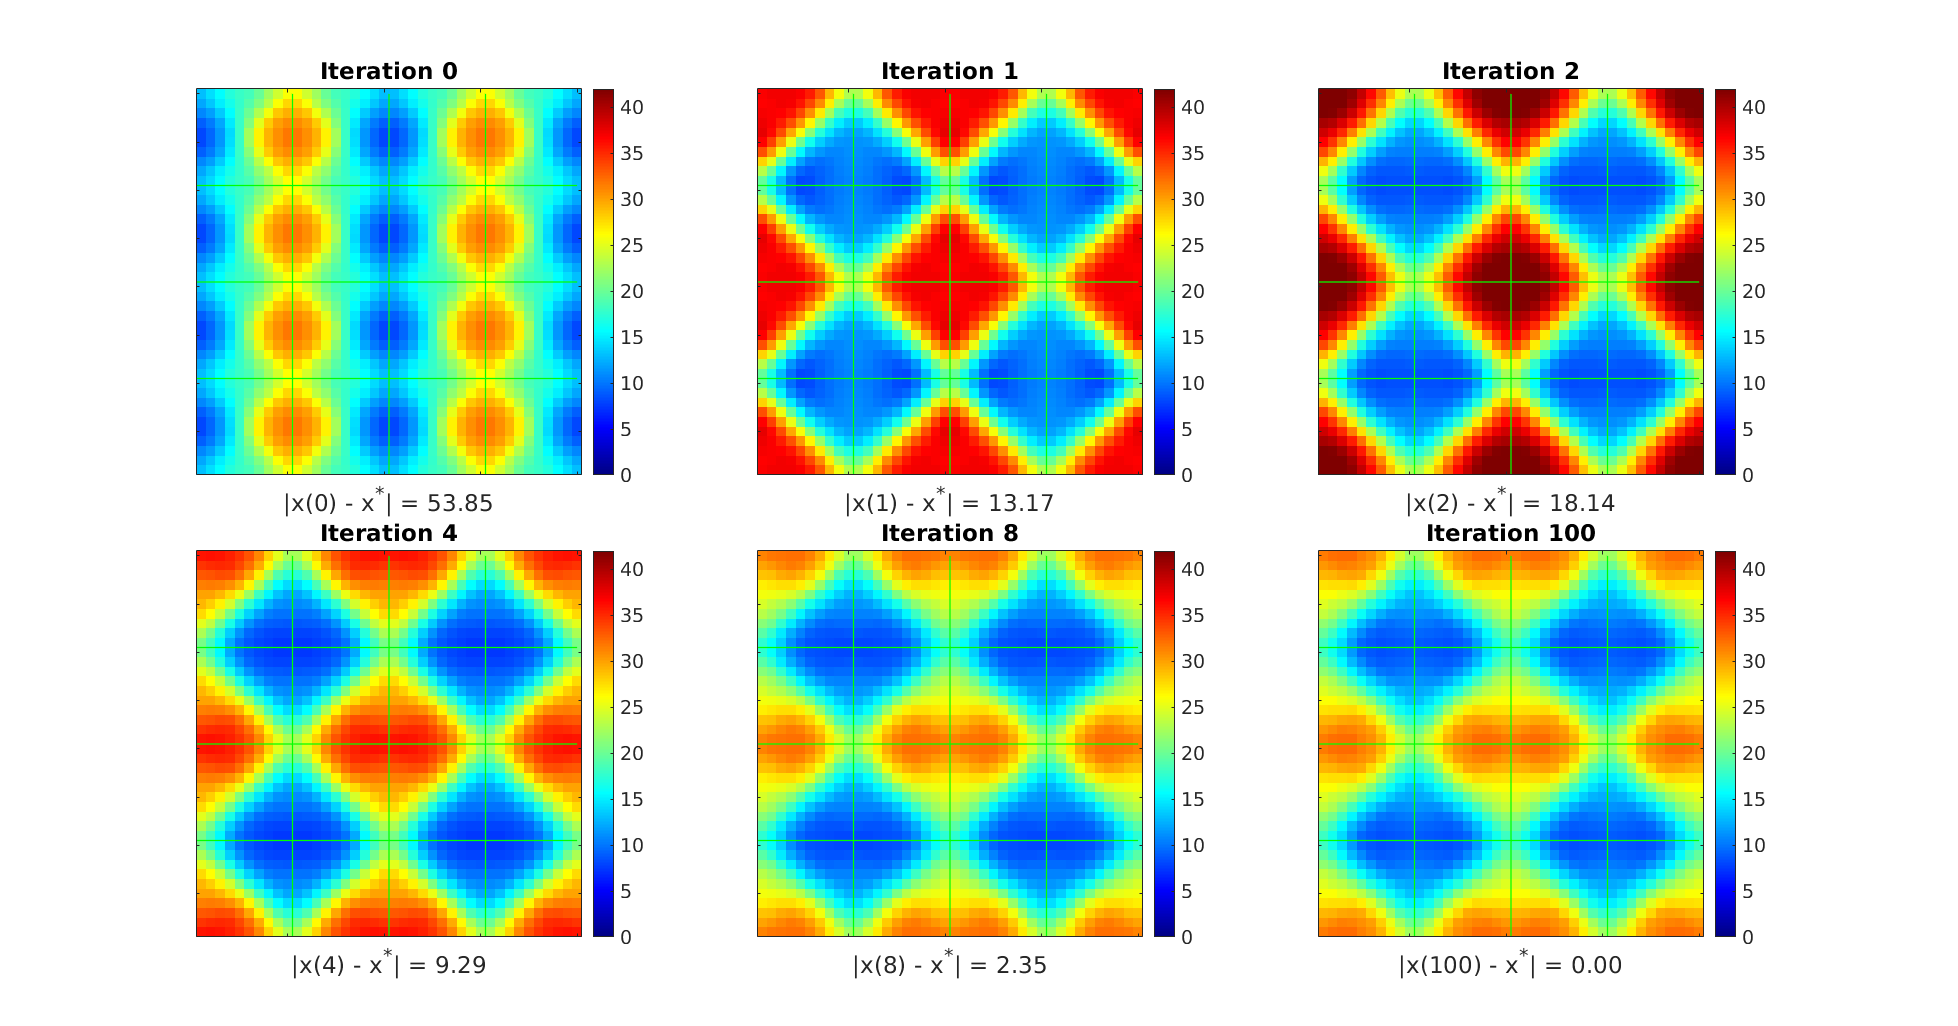

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)

Investigate the first one

PixX = [16, 20, 20]; PixY = [21, 21, 26];
for TestInd = 1:length(PixX)
    XX = PixX(TestInd); YY = PixY(TestInd); 
    PixInd = YY + (XX-1)*(N_HCOut*NPixY);
    LDE0 = LDEEpoOut{1}; LDE1 = LDEEpoOut{2};
    fprintf('Pix location: X%d, Y%d\n', XX, YY)
    fprintf('Initial Frs: fE = %.2f, fI = %.2f\n',LDE0.S(PixInd)*(1-CplxR)+LDE0.C(PixInd)*CplxR, LDE0.I(PixInd));
    fprintf('Iter1 Frs: fE = %.2f, fI = %.2f\n',LDE1.S(PixInd)*(1-CplxR)+LDE1.C(PixInd)*CplxR, LDE1.I(PixInd));
end

Pix location: X16, Y21


Initial Frs: fE = 17.93, fI = 62.23


Iter1 Frs: fE = 36.82, fI = 97.58


Pix location: X20, Y21


Initial Frs: fE = 13.03, fI = 46.17


Iter1 Frs: fE = 36.84, fI = 91.47


Pix location: X20, Y26


Initial Frs: fE = 8.17, fI = 39.68


Iter1 Frs: fE = 36.68, fI = 95.90
